clearvars
Ns = 2.^(7:13);
I1 = 2;
I2 = 1;
I3 = 1.1;
a1 = (I2- I3)/(I2*I3);
a2 = (I3 - I1)/(I3*I1);
a3 = (I1 - I2)/(I1*I2);
a = [a1,a2,a3]';
U0 = [1,0.1,0.01]';
N = 1e+4;
T = 1e+3;
h = T/(N-1);
time = 0:h:T;

C1 = diag([1,1,1]);

C2 = 1/2*diag([1/I1,1/I2,1/I3]);


U = zeros(3,1);

C1_const = zeros(1,N);
C2_const = zeros(1,N);


Uimp = U0;
Uimp_evalution = zeros(3,N);
Uimp_evalution(:,1)= Uimp;


C1_const(1) = Uimp'*C1 *Uimp;
C2_const(1) = Uimp'*C2 *Uimp;
Simp = 0;
Nimp = 0;
for i = 2:N
    U = U0 + h*fun(a,U0);
    err = 1;
    deltaErr = (h/T)^3;
    tic
    while(err > deltaErr)
        Uimp = U0 + h*fun(a,(U0+U)./2);
        err = norm(U -Uimp);
        U = Uimp;
        Nimp = Nimp +1;
    end
    Simp = Simp +toc;
    U0 = Uimp;
    
    Uimp_evalution(:,i) = Uimp;
    C1_const(i) = Uimp'*C1 *Uimp;
    C2_const(i) = Uimp'*C2 *Uimp;
end



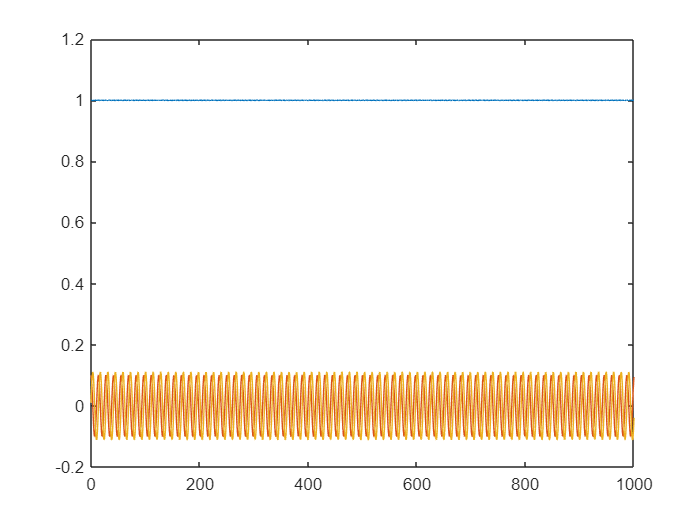

plot(time,Uimp_evalution);

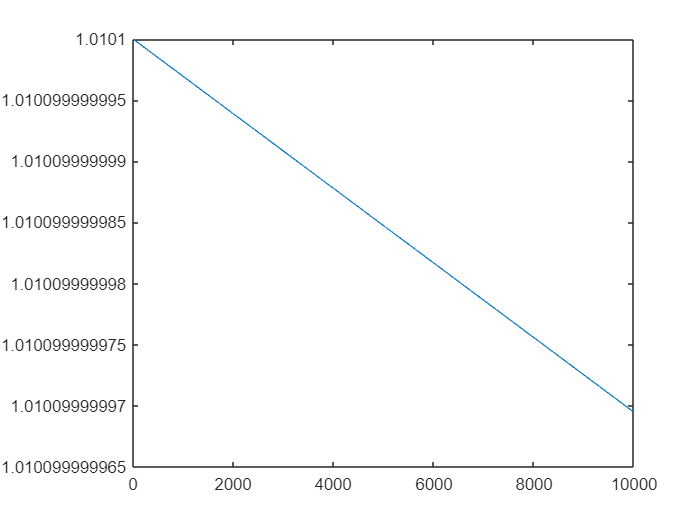

plot(C1_const);

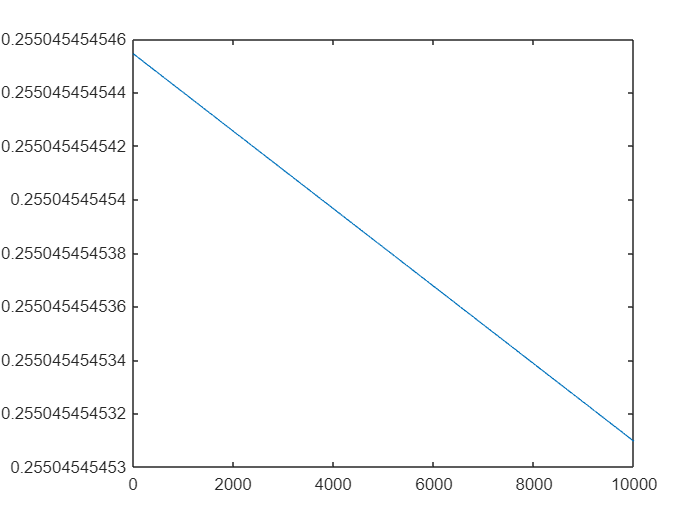

plot(C2_const);


C1_const = zeros(1,N);
C2_const = zeros(1,N);

UNew = U0;
UNew_evalution = zeros(3,N);
UNew_evalution(:,1)= U0;


C1_const(1) = UNew'*C1 *UNew;
C2_const(1) = UNew'*C2 *UNew;
SNew = 0;
NNew = 0;
for i = 2:N
    UNew = U0;
    deltaErr = (h/T)^3;
    Err = 1;
    tic
    while(Err > deltaErr)
        Fu = UNew - U0 - h*fun(a,(U0 +UNew)/2);
        dFu = dF(U0,UNew,h,a);
        dE =  dFu \ Fu;
        UNew = UNew - dE;
        Err = norm(dE);
        NNew = NNew +1;
    end
    SNew = SNew + toc;
    U0 = UNew;
    UNew_evalution(:,i) = UNew;
    C1_const(i) = UNew'*C1 *UNew;
    C2_const(i) = UNew'*C2 *UNew;
end

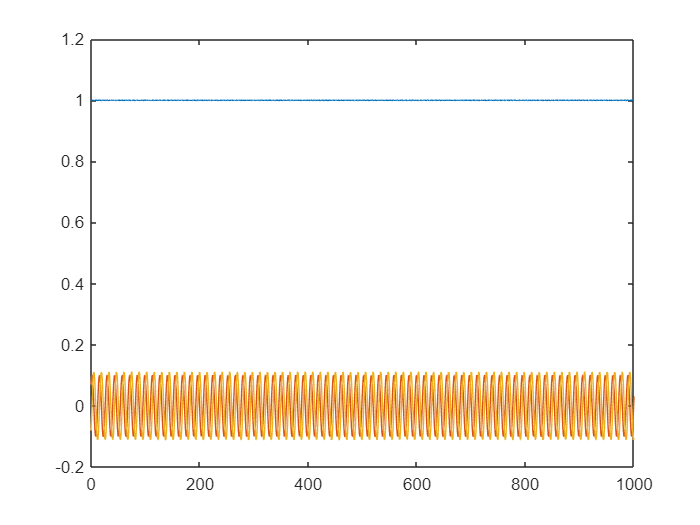

plot(time,UNew_evalution);

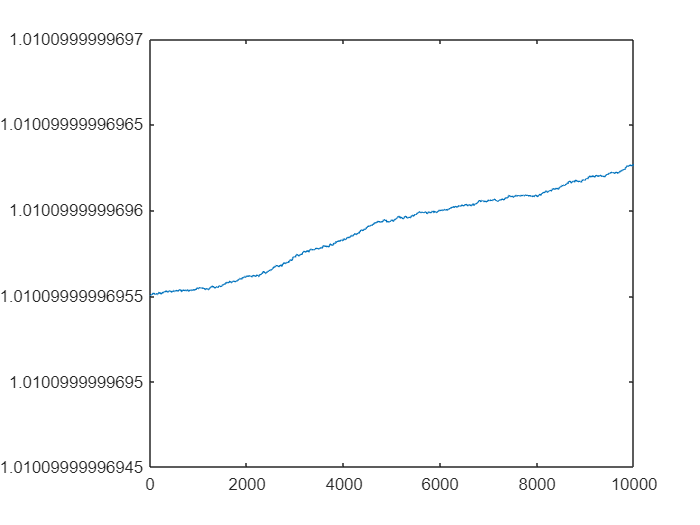

plot(C1_const);

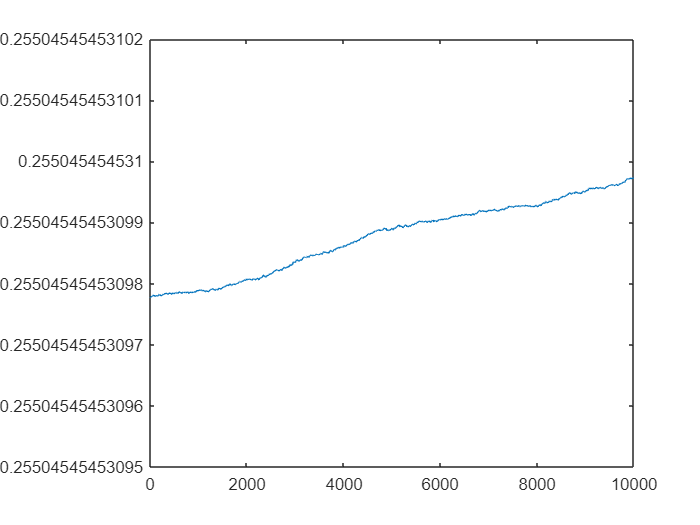

plot(C2_const);

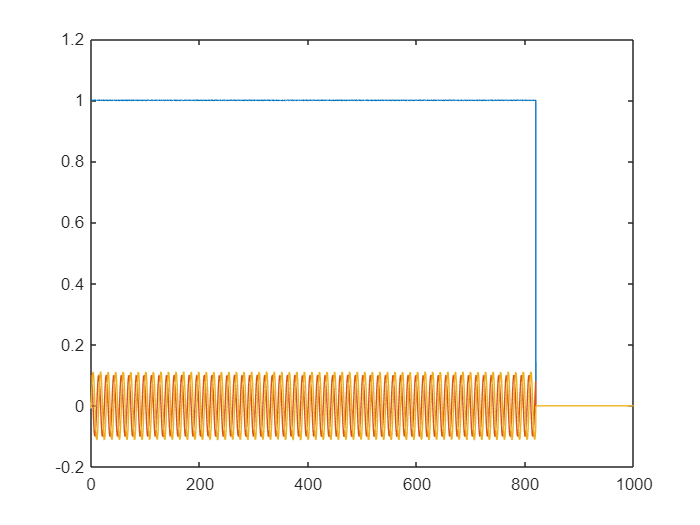

U0 = [1,0.1,0.01]';
C1_const = zeros(1,N);
C2_const = zeros(1,N);


ULimp = U0;
ULimp_evalution = zeros(3,N);
ULimp_evalution(:,1)= ULimp;


C1_const(1) = ULimp'*C1 *ULimp;
C2_const(1) = ULimp'*C2 *ULimp;
SLimp = 0;
NLimp = zeros(size(Ns));
L = 0.1;
j = 1;
for N = Ns
     
    
    for i = 2:N
    
        err = 1;
        deltaErr = (h/T)^3;
        Un = ULimp;
        ULimp = Un + h*fun(a,Un);
    
        while(err > deltaErr)
            Uprev = ULimp;
            ULimp = Un + h*fun(a,(Un + Uprev)./2);
            ULimp = L * ULimp + (1-L)*Uprev;
            err = norm(Uprev - ULimp);
            NLimp(j) = NLimp(j) +1;
        end
        
        
        ULimp_evalution(:,i) = ULimp;
        C1_const(i) = ULimp'*C1 *ULimp;
        C2_const(i) = ULimp'*C2 *ULimp;
    end
    j = 1+j;
end

plot(time,ULimp_evalution);

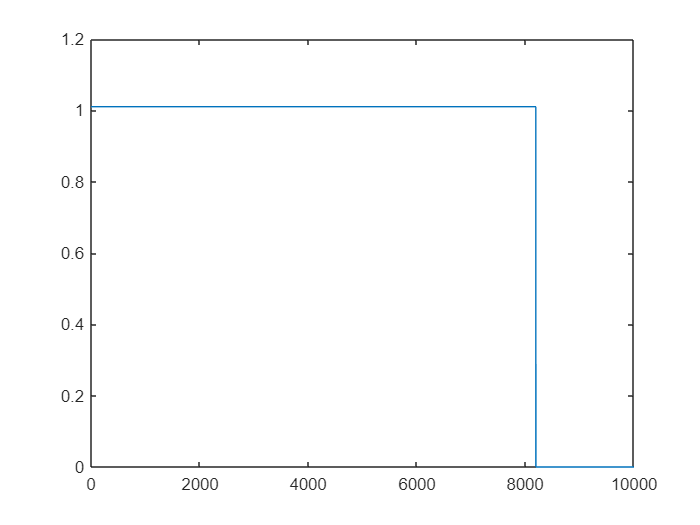

plot(C1_const);

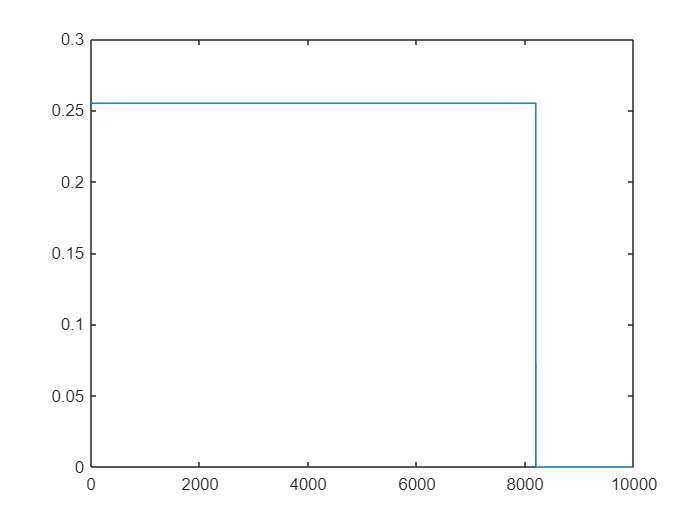

plot(C2_const);

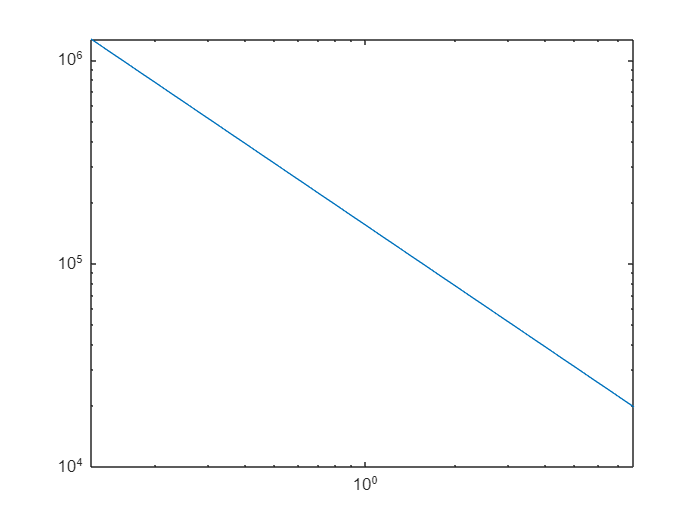

loglog(T./(Ns-1),NLimp)

function res = fun(a,U0)
    U = zeros(3,1);
    U(1) = (a(1) *U0(2)*U0(3));
    U(2) = (a(2) *U0(3)*U0(1));
    U(3) = (a(3) *U0(1)*U0(2));
    res = U;
end

function res = dF(U0,ksi,h,a)
    res = [1,-h*a(1)*(U0(3) + ksi(3))/4, -h*a(3)*(U0(2) + ksi(2))/4;
        -h*a(2)*(U0(3) + ksi(3))/4, 1 , -h*a(2)*(U0(1) + ksi(1))/4;
        -h*a(3)*(U0(2) + ksi(2))/4, -h*a(3)/4*(U0(1) + ksi(1))/4, 1];
end

function res = EulerExpl(h,U0,fun,a)
    res = U0 + h *fun(a,U0);
end

function res = EulerImp(h,U0,U1,fun,a)
    res = U0 + h * fun(a,(U0+U1)/2);
end